# bisection_algorithm

Zeri di una funzione in un dato intervallo attraverso l'applicazione del metodo di bisezione [1].

## Sintassi

x = bisection_algorithm(f,x0)
x = bisection_algorithm(f,x0,TOL)
x = bisection_algorithm(f,x0,TOL,NMAX)

x =    1.414213562373095


[x, output] = bisection_algorithm()
[x, output, graf] = bisection_algorithm()

## `Descrizione`

- `x = bisection_algorithm(f,x0) `cerca di trovare un punto `x` in cui f`(x)=0 `all'interno dell'intervallo specificato da `x0`. La soluzione si trova nel punto in cui f`(x)` cambia segno: gli estremi dell'intervallo devono essere necessariamente discordi.

- `x = bisection_algorithm(f,x0,TOL) `usa `TOL `per determinare l'accuratezza della soluzione. Se non specificato, `TOL=eps`.

- `x = bisection_algorithm(f,x0,TOL,NMAX) `usa `TOL `per determinare l'accuratezza della soluzione e `NMAX` per individuare il numero massimo di iterazioni che l'algoritmo può compiere. Se non specificati, `TOL=eps, NMAX=500`.

- `[x, output] = bisection_algorithm(___) `restituisce, oltre alla soluzione, una struttura `output `che contiene due campi: `fx` con il valore della funzione in `x`, `niter` con il numero di iterazioni eseguite dall'algoritmo.

- `[x, output, graf] = bisection_algorithm(___)` restituisce anche una variabile di tipo carattere `char`, fa il grafico della funzione e dello zero trovato.

## Esempi

**Calcolo zero a partire da un intervallo**

Trova lo zero della funzione $f(x) = x^2 - 2$ nell'intervallo $[0, 1]$.

f = @(x)(x.^2 - 2); % funzione
x0 = [1 2]; % intervallo iniziale
x = bisection_algorithm(f,x0)

x =    1.414062500000000


*Si osservi che, in questo caso, *`TOL=eps NMAX=500.`

**Calcolo zero specificando accuratezza e numero massimo di iterazioni**

Trova lo zero della funzione $f(x) = x^2 - 2$ nell'intervallo $[0, 1]$ con un accuratezza `TOL=1e-3` e `NMAX=50`

x =    3.921117013138087


output = struct with fields:
       fx: 0
    niter: 42


graf = 'Grafico disegnato.'

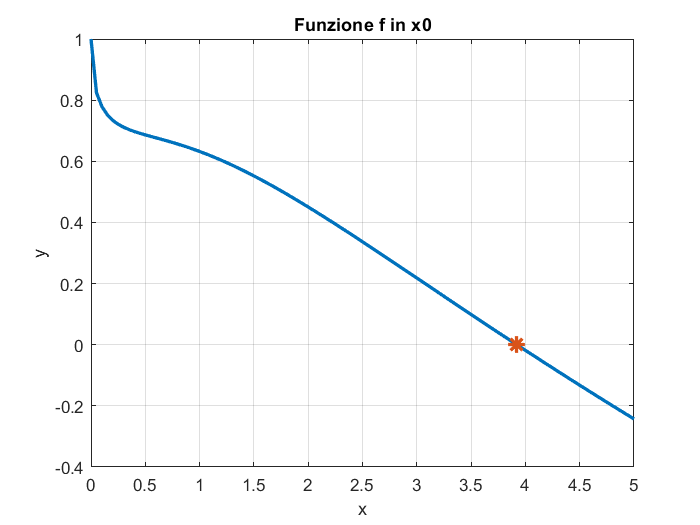

f = @(x)(x.^2 - 2); % funzione
x0 = [1 2]; % intervallo iniziale
x = bisection_algorithm(f,x0, 1e-2, 50)

**Calcolo zero specificando tutti i parametri di output**

Trova lo zero della funzione $f(x) = x^2 - 2$ nell'intervallo $[0, 1]$, ottenendo una struttura contenente il valore della funzione nel punto ottenuto e il numero massimo di iterazioni, e un grafico della funzione in cui viene messo in evidenza lo zero ottenuto.

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 5]; % intervallo iniziale
[x output graf] = bisection_algorithm(f,x0)

## Parametri di input

`f - funzione di cui bisogna trovare lo zero (``function handle)`

Funzione di cui calcolare lo zero, specificata come handle di funzione. L'algoritmo risolve` f(x)=0`. Per risolvere un'equazione del tipo `f(x)=c(x)`, è possibile utilizzare un handle definito come `f2=@(x)(f(x)-c(x))`.

*Esempio*:` @sin`

*Esempio*: `@myFunction`

*Esempio*: `@(x)(x^2 - 2)`

*Data Types*: `function_handle`

`x0 - Intervallo iniziale (array di 2 elementi)`

Intervallo iniziale, definito come un vettore costituito da due numeri reali. `bisection_algorithm` verifica che` f(x0(0))` e `f(x0(1)) `abbiano segni discordi, e mostra un errore se ciò non è verificato. Successivamente, restringe iterativamente l'intervallo per raggiungere la soluzione. L'intervallo x0 deve essere finito: non può contenere $\pm Inf$.

*Esempio: *`[2 17]`

*Data Types: *`double`

`TOL - Accuratezza (double)`

Parametro facoltativo. Valore di tolleranza per `x`. Il valore di default è `eps, `2.2204e-16.

*Data Types: *`double`

`NMAX - Limite iterazioni (integer)`

Parametro facoltativo. Numero massimo di iterazioni. Il valore di default è 500.

*Data Types: *`integer`

## Parametri di output

`x - Valore dell'approssimazione dello zero (reale scalare)`

Valore dell'approssimazione dello zero, restituita come uno scalare

`output - informazioni di output (struttura)`

Informazioni aggiuntive sul risultato ottenuto. I campi della struttura sono:

- `fx: `valore della funzione `f` nel punto `x`

- `niter: `numero di iterazioni compiute

`graf - stampa del grafico (char)`

Se questo parametro è specificato, l'algoritmo stampa il grafico della funzione nell'intervallo specificato, mostrando il punto in cui è stato calcolato lo zero della funzione. La variabile `graf` assume il valore `'Grafico disegnato.'`.

## Riferimenti

[1] Corliss, George,* "Which root does the bisection algorithm find?"*, *SIAM Review*, 1977

## Autori

Valerio La Gatta, Marco Postiglione